# `ScatterFitChart`** Examples**

**Overview**

The `ScatterFitChart` manages bivariate scattered data together with the associated best-fit trend line (regression line). The chart data comprises numeric vectors `XData` and `YData`. The `YData` is scattered against the `XData` and the best-fit line is computed using the `fitlm` function to perform linear regression.

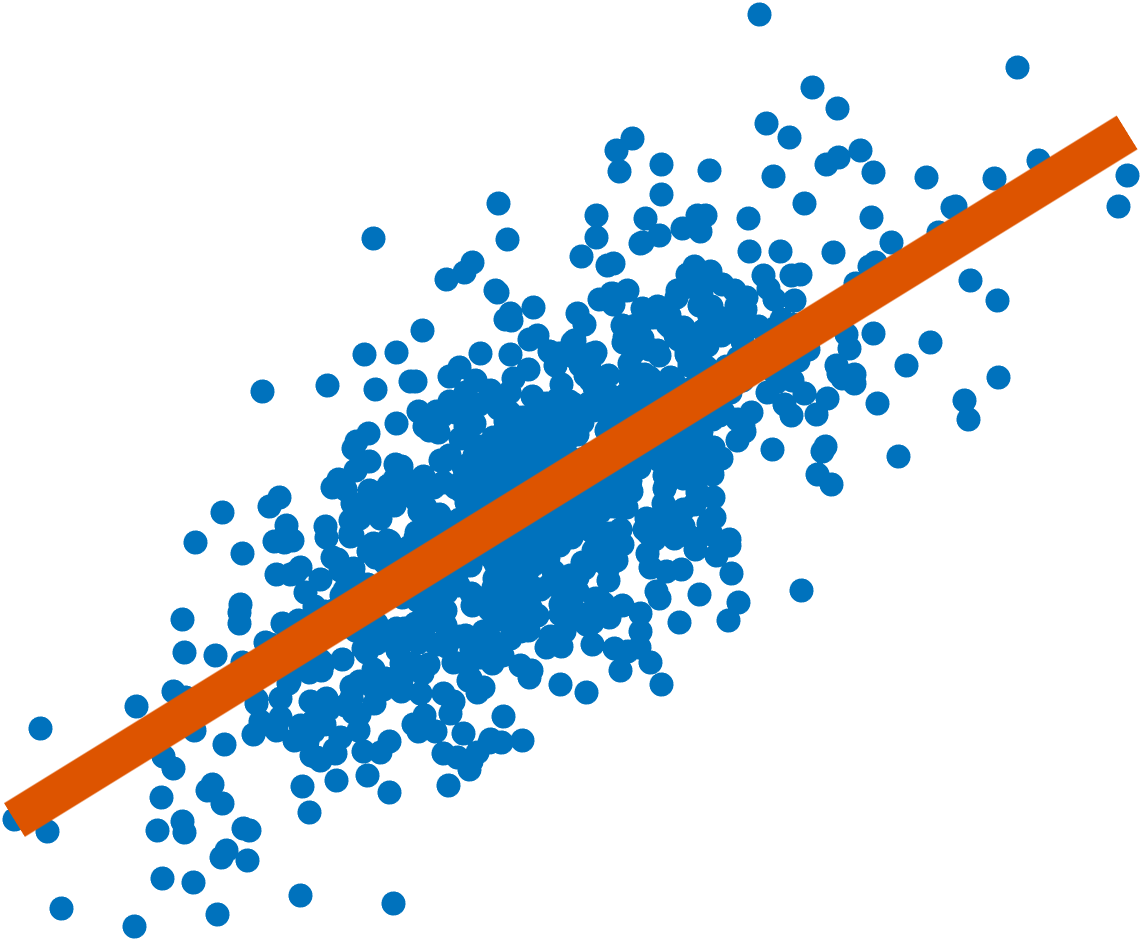

**Resources**

[Open](matlab: edit( fullfile( catalogRoot(), "+example", "ScatterFit.mlx" ) )) this Live Script to run and interact with the examples shown below.

[View](matlab: edit( fullfile( catalogRoot(), "+chart", "ScatterFit.m" ) )) the source code for the `ScatterFitChart`.

Documentation for:

- [`scatter`](matlab: doc( "scatter" )): create a scatter plot with variable marker color and size

- [`fitlm`](matlab: doc( "fitlm" )): fit a linear regression model

## Create sample x and y data for the chart.

rng( "default" )
x = randn( 1000, 1 );
y = 2 * x + 1 + 2 * randn( size( x ) );

## Create a figure for the chart.

f = exampleFigure( "Name", "ScatterFitChart Example" );

## Create the chart.

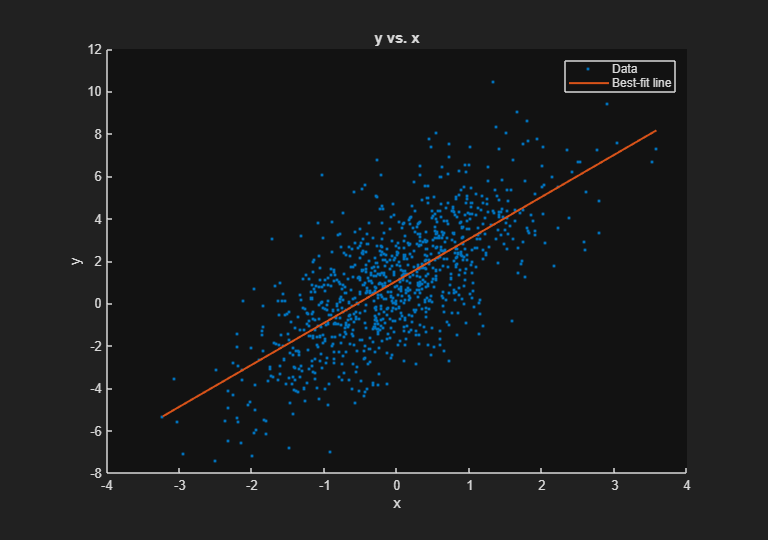

SFC = ScatterFitChart( "Parent", f, ...    
    "XData", x, ...
    "YData", y );

## Annotate the chart.

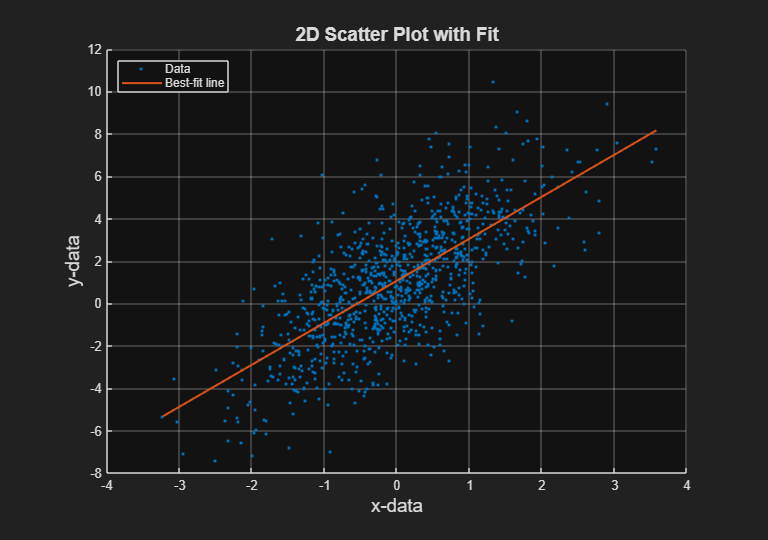

xlabel( SFC, "x-data", "FontSize", 14 )
ylabel( SFC, "y-data", "FontSize", 14 )
title( SFC, "2D Scatter Plot with Fit", "FontSize", 14 )
grid( SFC, "on" )
legend( SFC, "Location", "northwest" );

## Customize the chart by adjusting its graphics properties.

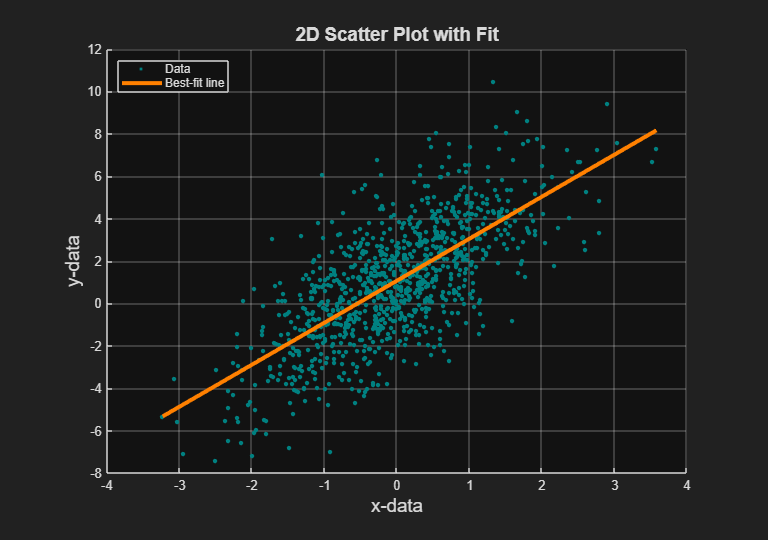

SFC.LineColor = [1, 0.5, 0];
SFC.LineWidth = 3;
SFC.CData = [0, 0.5, 0.5];
SFC.SizeData = 100;
SFC.Controls = "off";

## Update the chart data.

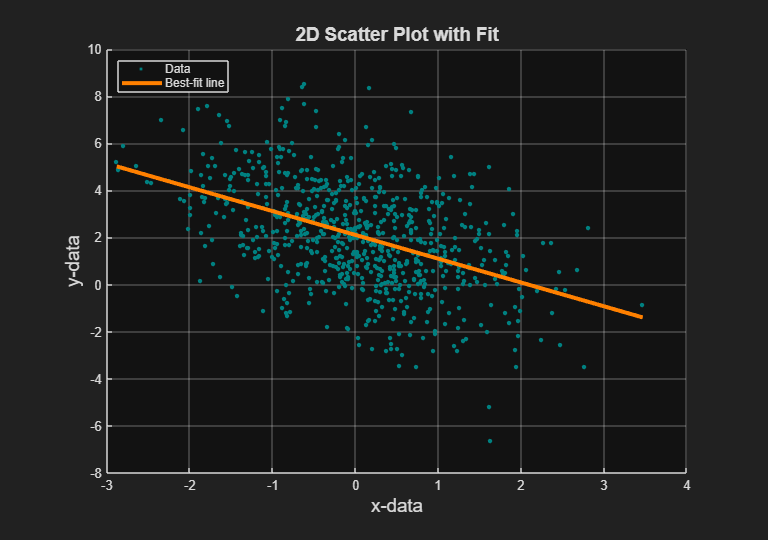

SFC.XData = randn( 750, 1 );
SFC.YData = (-1) * SFC.XData + 2 + 2 * randn( size( SFC.XData ) );

*Copyright 2018-2025 The MathWorks, Inc.*